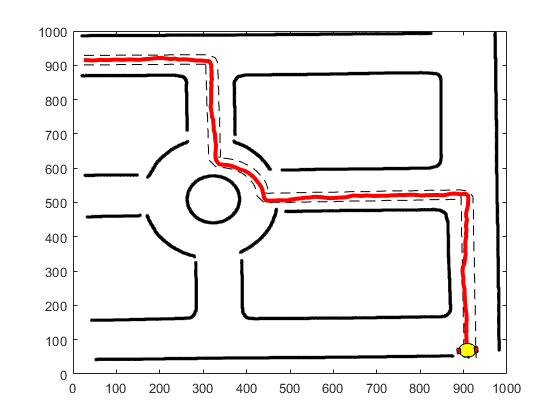

clear all
clc

% 
% map = importdata("trajectory.mat");
% map = flip(map);
% % map = map';% recieve path
% position = importdata('trajectory_centroid.mat'); % points for robot centroid path
% % r = .1; % base robot circle radius 
% % r2 = r/5; % pin radius
% % d = r/2.5; % size of wheels

map = importdata("referencetrajectory_map_without.mat"); % recieve path
position = importdata("referencetrajectory.mat");

centroid = importdata("road_error_centroid.mat"); % points for robot centroid path
tolerance1 = importdata("tolerance1.mat");
tolerance2 = importdata("tolerance2.mat");

r = 20; % base robot circle radius 
r2 = r*.15; % pin radius
d = r*.4; % size of wheels


limit = 7;
% down_sample_amount = 5;
% traj_velocity = importdata("UNCC_ACRONYM_CENTROID.mat");
% all = importdata("trajectory_data.mat")
% all = struct2cell(all);
% trajectory = all{2};
% map = trajectory;
% position = traj_velocity;

% map = map';
% position = importdata('posterPoints_centroid.mat'); % points for robot centroid path
% r = 1; % base robot circle radius 
% r2 = r/5; % pin radius
% d = r/2.5; % size of wheels

% map = importdata("posterPoints.mat");
% map = map';% recieve path
% position = importdata('posterPoints_centroid.mat'); % points for robot centroid path
% r = 50; % base robot circle radius 
% r2 = r/5; % pin radius
% d = r/2.5; % size of wheels

% calculate points for wheels and pin location
zb(1,:) = centroid(1,:) + r*cos(centroid(3,:));
zb(2,:) = centroid(2,:) + r*sin(centroid(3,:));
topWheel(1,:) = centroid(1,:) + r*cos(pi/2+centroid(3,:));
topWheel(2,:) = centroid(2,:) + r*sin(pi/2+centroid(3,:));
bottomWheel(1,:) = centroid(1,:) - r*cos(pi/2+centroid(3,:));
bottomWheel(2,:) = centroid(2,:) - r*sin(pi/2+centroid(3,:));

% plot initial wheels and pin location
[xcircle,ycircle] = circle(centroid(:,1),r);
[x2circle,y2circle] = circle(zb(:,1),r2);
[a1,b1] = rectangle(topWheel(:,1), centroid(3,1),d);
% plot Map and initial position 
figure
% plot(map(1,:), map(2,:),'Color',[0.9290 0.6940 0.1250])
plot(map(1,:), map(2,:)+20,'.','color','k')


hold on
plot(tolerance1(1,:),tolerance1(2,:),'--','color','k')
plot(tolerance2(1,:),tolerance2(2,:),'--','color','k')
% xlim([0 3.5])
% ylim([0 3.5])
% xlim([min(zb(1,:))-r*limit max(zb(1,:))+r*limit ])
% ylim([min(zb(2,:))-r*limit  max(zb(2,:))+r*limit ])

h3 = plot(zb(1,1), zb(2,1),'Color','r','linewidth',3);
h1 = fill(xcircle, ycircle,'y'); % robot
h2 = fill(x2circle,y2circle,'k'); % base-point
Wheel1 = fill(a1, b1,'r');
Wheel2 = fill(a1, b1,'r');
% legend('Reference Trajectory', 'Robot', "location", 'best')

% plot robot location at each positon and update plot
for k = 1:length(centroid)
% for k = 1:2
    [a,b] = circle(centroid(:,k), r);
    [x2circle,y2circle] = circle(zb(:,k), r2);
    [a1,b1] = rectangle(topWheel(:,k), centroid(3,k),d);
    set(Wheel1, 'XData', a1,'YData', b1);
    
    current_posx(k) = zb(1,k);
    current_posy(k) = zb(2,k);  
% 
%     plotted_x = current_posx(1,k); plotted_y = current_posy(2,k);
    set(h3, 'XData',  current_posx, 'YData', current_posy)

    [a1,b1] = rectangle(bottomWheel(:,k), centroid(3,k),d);
    set(Wheel2, 'XData', a1,'YData', b1);
    set(h1, 'XData',a,'YData', b);
    set(h2, 'XData', x2circle,'YData', y2circle);
    drawnow
   
  frame(k) = getframe(gcf);
end

video = VideoWriter('road_animation_tolerance',"MPEG-4");
video.FrameRate = 50;
open(video)
writeVideo(video, frame);
close(video);

function [a,b] = circle(position,r) % function to plot circle
    th = 0:pi/100:2*pi; % plot circle with step size of pi/100
    a = r*cos(th)+position(1); % x position
    b = r*sin(th)+position(2); % y location
end

function [a1,b1] = rectangle(x,theta,d) % function to plot rectangle
% initialize distances between edges of the rectangle 
sx = [-d  d  d  -d]; 
sy = [-d/2  -d/2  d/2  d/2];
% calcualte 1x4 array with final ege points
a1 = sx*cos(theta) - sy*sin(theta) + x(1);
b1 = sx*sin(theta) + sy*cos(theta) + x(2);
end